%% Hw3-Part2-1: MAP-based Change Point Detection
clc; clear; close all;

%% Parameters
N = 800;            % Total number of data points
T0 = 400;           % True change point
rho = 0.8;          % AR(1) coefficient
phi = pi/4;         % AR(2) pole angle
sigma_alpha = 1;    % Standard deviation of noise for AR(1)
sigma_beta = 1;     % Standard deviation of noise for AR(2)
MC = 3000;          % Number of Monte Carlo simulations

% Compute AR(2) coefficients
a1 = rho * cos(phi);    % AR(2) coefficient a1
a2 = -rho^2 / 4;        % AR(2) coefficient a2

%% Monte Carlo Simulation
mse_values = zeros(MC, 1);  % Store MSE results

for mc = 1:MC
    % Generate AR(1) process (for n ≤ T0)
    x = zeros(N, 1);
    x(1) = sqrt(sigma_alpha) * randn; % Initial value
    for n = 2:T0
        x(n) = rho * x(n-1) + sqrt(sigma_alpha) * randn;
    end
    
    % Generate AR(2) process (for n > T0)
    x(T0+1) = sqrt(sigma_beta) * randn; % Initial value
    x(T0+2) = sqrt(sigma_beta) * randn;
    for n = T0+3:N
        x(n) = a1 * x(n-1) + a2 * x(n-2) + sqrt(sigma_beta) * randn;
    end

    %% Compute A-Posteriori Probability for Each Candidate T_hat
    log_posterior = -inf(N, 1);  % Log posterior probabilities (initialize to -inf)

    for T_hat = 2:N-2
        % Compute residuals for AR(1) (n = 2 to T_hat)
        if T_hat > 2
            e_AR1 = x(2:T_hat) - rho * x(1:T_hat-1);
            RSS1 = sum(e_AR1.^2);
        else
            RSS1 = inf; % Avoid index error for small T_hat
        end

        % Compute residuals for AR(2) (n = T_hat+3 to N)
        if (N - (T_hat+2)) >= 1
            e_AR2 = x(T_hat+3:N) - a1*x(T_hat+2:N-1) - a2*x(T_hat+1:N-2);
            RSS2 = sum(e_AR2.^2);
        else
            RSS2 = inf;
        end

        % Compute log posterior probability (proportional to negative RSS)
        log_posterior(T_hat) = -0.5 * (RSS1 + RSS2);
    end

    % Normalize posterior probability
    posterior = exp(log_posterior - max(log_posterior)); % Avoid numerical underflow
    posterior = posterior / sum(posterior);

    % Estimate T_0 using Maximum A-Posteriori (MAP)
    [~, T_hat_opt] = max(posterior);
    
    % Compute squared error
    mse_values(mc) = (T_hat_opt - T0)^2;
end

%% Compute Final Mean Squared Error (MSE)
MSE = mean(mse_values);
fprintf('Monte Carlo estimated MSE: %.4f\n', MSE);

Monte Carlo estimated MSE: 920.3907


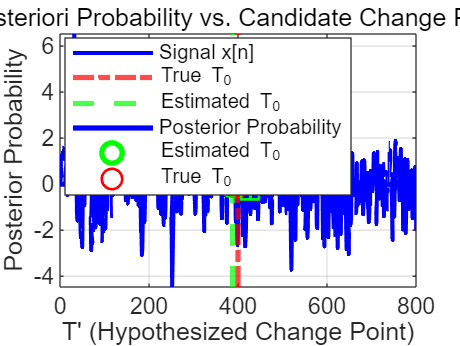


%% Plot Results for the Last Simulation
figure(1);
plot(x, 'b', 'LineWidth', 1.5); hold on;
xline(T0, '-.r', 'LineWidth', 2, 'Label', 'True T_0');
xline(T_hat_opt, '--g', 'LineWidth', 2, 'Label', 'Estimated T_0');
title('Generated Signal (AR(1) + AR(2))');
xlabel('Time n');
ylabel('x[n]');
legend('Signal x[n]', 'True T_0', 'Estimated T_0', 'Location', 'best');
grid on;

%% Plot Posterior Probability vs. Candidate Change Point T_hat
figure(2);
plot(2:N-2, posterior(2:N-2), 'b', 'LineWidth', 2, 'DisplayName', 'Posterior Probability');
hold on;
plot(T_hat_opt, posterior(T_hat_opt), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Estimated T_0');
plot(T0, posterior(T0), 'ro', 'MarkerSize', 10, 'LineWidth', 1, 'DisplayName', 'True T_0');

title('A-Posteriori Probability vs. Candidate Change Point T''');
xlabel('T'' (Hypothesized Change Point)');
ylabel('Posterior Probability');
legend('show');
grid on;